# Process Aperture data

This calculates the following: accuracy, R^2, and response times (which includes significant changes in movement). 

## Subject specific info:

filePath: the path to the .mat files (converted from Tanks) for each subject; currently specific to Macademia computer

stims: the two stim channels: [active ground]

trials: useable trials from all Tank files (i.e. the runs that were actually completed)

trials_NV: the trials without visual feedback (i.e., trials with only stim feedback)

practiceTrials: 1: trials that have the straight beginning and then the sine wave begins halfway through the trial; 0: normal (sine) paths. This is used when determining the start and end times of the trial.

sid = 'ecb43e';
switch(sid)
    case 'fca96e'
        filePath = 'C:\Users\jcronin\Data\Subjects\fca96e\data\d7\fca96e_Aperture\Matlab\Aperture-';
        stims = [4 5];
        trials = [2 5 7 8 9 10 12 13 15 16 17];
        trials_NV = [5 7 8 9 10 17];
        practiceTrials = [1 0 0 0 0 0 1 1 1 1 0];
        
    case 'ecb43e'
        filePath = 'C:\Users\jcronin\Data\Subjects\ecb43e\d7\Aperture_ecb43e\Matlab, Aperture\Aperture_ecb43e-';
        stims = [47 46];
        trials = [4 5 6 8 9 10 11 12 13 14 15 16 18 19];
        trials_NV = [4 9 10 11 12 13 14 15 16 18 19];
        practiceTrials = zeros(size(trials)); % Did not have any practice trials as defined above
        
    case 'cdceeb'
        filePath = 'C:\Users\jcronin\Data\Subjects\cdceeb (wrong-f3e511)\data\d14\Aperture_cdceeb\Matlab\ApertureCheck-';
        stims = [59 51];
        trials = [1 2 3];
        trials_NV = [1 2 3];
        practiceTrials = zeros(size(trials)); % Did not have any practice trials as defined above
        
    otherwise
        error('unknown SID entered');
end


## Initialize vectors for saving trial by trial values

startTime and endTime: when to start and end the trial, cuts out data before the stim started and after the trial ended

accuracy and rsq (R^2) values for subject accuracy, average chance accuracy, and std deviations of the chance accuracies (run 1000 times)

responseTime: time from beginning of new stim (error) train to any 'significant change in motion'          CHECK THIS

responseTimeCorrect: time from beginning of new stim (error) train to any 'significant change in motion' that results in a desired correction (i.e. this is only the response times for when the subject correctly re-enters the target region) 

correctionTime: time from beginning of new stim (error) train to reentering the target region

- Each of the above (response times and correction times) has two cells: one for times from when they were too open, and one for times when they were too closed. 

startTime = zeros(length(trials), 1);
endTime = zeros(length(trials), 1);
accuracy = zeros(1, length(trials));
chanceAccuracy = zeros(1, length(trials));
std_chanceAccuracy = zeros(1, length(trials));
rsq = zeros(1, length(trials));
chanceRsq = zeros(1, length(trials));
std_chanceRsq = zeros(1, length(trials));
responseTimeCorrect_open = cell(length(trials), 1);
responseTimeCorrect_closed = cell(length(trials), 1);
responseTime_open = cell(length(trials), 1);
responseTime_closed = cell(length(trials), 1);
correctionTime_open = cell(length(trials), 1);
correctionTime_closed = cell(length(trials), 1);


## Loop through all trials for given subject and calculate: accuracy, R^2, and response times

for i=9:9; %length(trials)
    fileName = strcat(filePath, num2str(trials(i)));
    load(fileName);
    %aper = Aper.data(:,3);
    fs_aper = Aper.info.SamplingRateHz; % sampling rate of the stim data (Hz)
    t_aper = (0:1:length(Aper.data(:,1))-1)/fs_aper; % stim timing (s)
    fs_stim = Stim.info.SamplingRateHz;
    % Make sure the below is used:
    stim_time = (0:length(Stim.data(:,1))-1)/fs_stim;
    
    

Calculate the start and end times:

    if practiceTrials(i) == 1
        [startTime(i), endTime(i)] = aper_startANDendTimes(Aper.data(:,3), t_aper, 'yes');
    elseif practiceTrials(i) == 0
        [startTime(i), endTime(i)] = aper_startANDendTimes(Aper.data(:,3), t_aper, 'no');
    else
        error('practiceTrials array must only include 0s and 1s');
    end
    
    startSampAper = floor(startTime(i)*fs_aper);
    endSampAper = floor(endTime(i)*fs_aper);
    data = Aper.data(startSampAper:endSampAper,1);
    high_boundary = Aper.data(startSampAper:endSampAper,2);
    low_boundary = Aper.data(startSampAper:endSampAper,3);
    % Make sure the two below are used:
    startSampStim = floor(startTime(i)*fs_stim);
    endSampStim = floor(endTime(i)*fs_stim);

 Get filtered signal and find the points of significant change in movement:

    %[locs_movement, data_interp, data_filt, dx3] = aper_coherence_3(Aper, Stim, startTime(i), endTime(i));

Calculate the accuracy:

This returns a matrix of the 1000 shuffled position vectors that will be used in the R^2 analysis

    % Accuracy:
    accuracy(i) = sum(data < high_boundary & data > low_boundary)/length(data);
    % Chance accuracy calculations:
    [pos_shuffled, entersTarget, chanceAccuracy(i), std_chanceAccuracy(i)] = aper_chanceAccuracy(data, high_boundary, low_boundary);
    

Calculate the R^2 values:  CHECK THESE!!

    % center_boundary is the 'ideal'/model path between the two low and high target boundaries
    center_boundary = (high_boundary(entersTarget:end) + low_boundary(entersTarget:end))./2;
    [rsq(i)] = lmrsquare(center_boundary, data(entersTarget:end));
    % Chance R^2 calculations (use the same 1000 shuffled positions from accuracy calculation):
    [chanceRsq, std_chanceRsq] = rsquare_chance(center_boundary, pos_shuffled);
    
    %% Maybe should be calculating the true R2 value based on the entire path, not just from after they enter the target boundary... ?
    % center_boundary is the 'ideal'/model path between the two low and high target boundaries
    center_boundary2 = (high_boundary + low_boundary)./2;
    [rsq2(i)] = lmrsquare(center_boundary2, data);
    

## Calculate the significant changes in movement:

    % Get filtered signal and find the points of significant change in movement
    [locs_movement, data_interp, data_filt, dx3] = aper_coherence_3(Aper, Stim, startTime(i), endTime(i));

## Find when the stim state changes:

Using StimStarts and not StimTable, because StimTable still has issues with recognizing state changes. It does not handle finding state changes of no stim (i.e. it can only recognize when stim changes amplitude). Even then, it also can't handle/catch state changes when the stim amplitude changes in the middle of a train. For this type of code still use StimStarts. 

    ITI0 = max(Stm0.data(:,11));
    ITI1 = max(Stm1.data(:,11));
    if strcmp(sid, 'cdceeb')
        amp0 = max(Stm0.data(:,1))/2; % because amp was divided across two electrodes
        amp1 = max(Stm1.data(:,1))/2;
    else
        amp0 = max(Stm0.data(:,1));
        amp1 = max(Stm1.data(:,1));
    end
    PTD = max(Stm0.data(:,8));
    IPI = max(Stm0.data(:,5));
    [stimChanges, stimPks, ~] = StimStarts(Stim.data(startSampStim:endSampStim,4), Fs_stim, ITI0, ITI1, amp0, amp1, PTD, IPI, 'on');
    % Convert the stim start and end sample numbers from stim samples to ECoG
    % wave samples (ECoG was sampled slower):
    fac = fs_stim/fs_wave;
    stimChanges_aperSamps = floor(stimChanges/fac);
    
    
    

Account for the delay between setting the stim output and recording stim output (StimStarts was based off of setting the IZ current output and there's delay between setting the current and getting the voltage change):

    % Automate the delay detection:
    [~, loc_realized] = findpeaks(Stim.data(:,5)/max(Stim.data(:,5)),'NPeaks',1, 'MinPeakHeight', 0.5);
    % find the first instance when a value in the 1st row of stimTable (the
    % burst starts) is less than loc_realized, starting from the end of the
    % stimTable, and then add the pulse duration/2 to get to the last high
    % sample of the biphasic pulse:
    loc_set = find(stimTable(1,:)<loc_realized, 1, 'last');
    loc_set = stimTable(1,loc_set)+PD/2;
    delay = abs(loc_realized-loc_set);
    
    % Visualize delay:
    figure(2), hold off
    subplot(2,1,1), plot(stim.data(:,4)/max(stim.data(:,4)), 'k')
    hold on, plot(stim.data(:,5)/max(stim.data(:,5)), 'r')
    scatter(loc_realized, stim.data(loc_realized, 5)/max(stim.data(:,5)), 'c', 'filled')
    scatter(loc_set, stim.data(loc_set, 4)/max(stim.data(:,4)), 'y', 'filled')
    title('Delay, not shifted')
    subplot(2,1,2), plot(t_stim+delay/fs_stim, stim.data(:,4)/max(stim.data(:,4)), 'k')
    hold on, plot(t_stim, stim.data(:,5)/max(stim.data(:,5)), 'r')
    title('Shifted')
    
    % Convert the stim start and end sample numbers from stim samples to
    % ECoG wave samples:
    burstStarts = floor((stimTable(1,:)+delay)/fac);
    burstEnds = floor((stimTable(2,:)+delay)/fac);
    
    % Cut out and burst sample numbers after the stim is unarmed at the
    % end:
    burstStarts = burstStarts(burstStarts<endSampECoG);
    burstEnds = burstEnds(burstEnds<endSampECoG);
    % Also shift the sample numbers to cut out the time before the stim was
    % armed:
    burstStarts = burstStarts - startSampECoG;
    burstEnds = burstEnds - startSampECoG;
    % Since more ends could get cut than starts, check lengths and cut
    % starts from the end if they don't have a corresponding end
    if length(burstStarts)>length(burstEnds)
        burstStarts = burstStarts(1:length(burstEnds));
    end
    
    % Cut out any negative sample numbers due to stim not being armed
    % yet:
    temp = burstStarts>0;
    burstStarts = burstStarts(temp);
    burstEnds = burstEnds(temp);
    category = category(temp);

## Calculate the response times:

Response time from beginning of new stim (error) to any 'significant change in motion':

    % Response timing
    [responseTime_open{i}, responseTime_closed{i}] = aper_responseTime(locs_movement, stimChanges_aperSamps, stimPks, Stm1, Fs_aper, amp1);
    

Correct response times: those from the beginning of new stim (error) train to any 'significant change in motion' that results in the desired/correct correction (i.e. re-entering the target region):

Correction times from beginning of new stim (error) train to reentering the target region:

    % Correction timing
    locs_reenters_open = find(data(1:end-1)>high_boundary(1:end-1) & data(2:end)<high_boundary(2:end));
    locs_reenters_closed = find(data(1:end-1)<low_boundary(1:end-1) & data(2:end)>low_boundary(2:end));
    
    [correctionTime_open{i}, correctionTime_closed{i}] = aper_correctionTime(locs_reenters_open, locs_reenters_closed, stimChanges_aperSamps, stimPks, Stm1, Fs_aper);
    

Undefined function or variable 'stimChanges_aperSamps'.


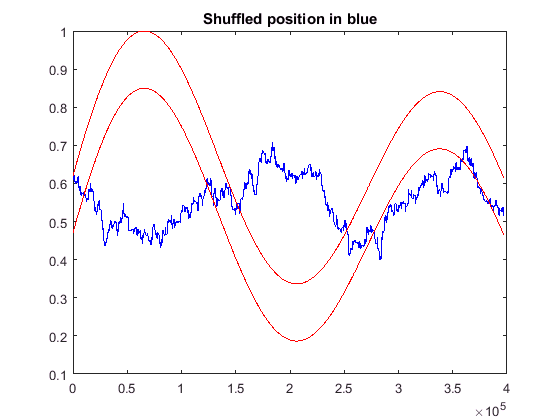

    
end